# 1.读取原始数据

data = readmatrix('ratings.csv');%读数据
data = data(:,1:3);%删去时间戳
data

data = 	1.0e+05 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0001    0.0000
    0.0000    0.0005    0.0001
    0.0000    0.0005    0.0001
    0.0000    0.0007    0.0000
    0.0000    0.0010    0.0001
    0.0000    0.0011    0.0000
    0.0000    0.0015    0.0001
    0.0000    0.0016    0.0001


% 将电影ID映射为从1~n
all_item = unique(data(:,2));
for i=1:size(data,1)
    data(i,2) = find(all_item==data(i,2));
end
data

data = 	1.0e+03 *

    0.0010    0.0010    0.0040
    0.0010    0.0030    0.0040
    0.0010    0.0060    0.0040
    0.0010    0.0440    0.0050
    0.0010    0.0470    0.0050
    0.0010    0.0630    0.0030
    0.0010    0.0900    0.0050
    0.0010    0.0980    0.0040
    0.0010    0.1250    0.0050
    0.0010    0.1310    0.0050


## 2.数据集划分

% 分为训练集与测试集
selected = randperm(size(data,1));
train_number = floor(size(selected,2)*0.8)

train_number = 80668

test_number = size(data,1)-train_number

test_number = 20168

train_data = data(selected(1:train_number),:);
test_data = data(selected(train_number+1:end),:);

% 训练集构造交互矩阵
numberOfUser = size(unique(data(:,1)),1);
numberOfItem = size(unique(data(:,2)),1);
interactionMatrix_train = zeros(numberOfUser,numberOfItem);
for i=1:size(train_data,1)
    if data(i,3)>=3
        interactionMatrix_train(train_data(i,1),train_data(i,2))=1;
    end
end
interactionMatrix_train

interactionMatrix_train =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     

% 测试集构造交互矩阵
interactionMatrix_test = zeros(numberOfUser,numberOfItem);
for i=1:size(test_data,1)
    if data(i,3)>=3
        interactionMatrix_test(test_data(i,1),test_data(i,2))=1;
    end
end
interactionMatrix_test

interactionMatrix_test =      0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0

## 3.MF分解矩阵,初始化User，Item

[User,Item] = nnmf(interactionMatrix_train,20);
epoch = 1000;
regulation_index = 0.01;
learning_rate = 0.01;

## 4.训练

auc = zeros(1,11);
auc(1) = AUC(User,Item,interactionMatrix_test);
original_auc = zeros(1,11);
original_auc(:) = auc(1);
for i=1:epoch
   [User,Item] = Vtrain(User,Item,interactionMatrix_train,learning_rate,regulation_index);
   if mod(i,100) == 0
       auc(i/100+1) = AUC(User,Item,interactionMatrix_test);
   end
end

## 5.结果

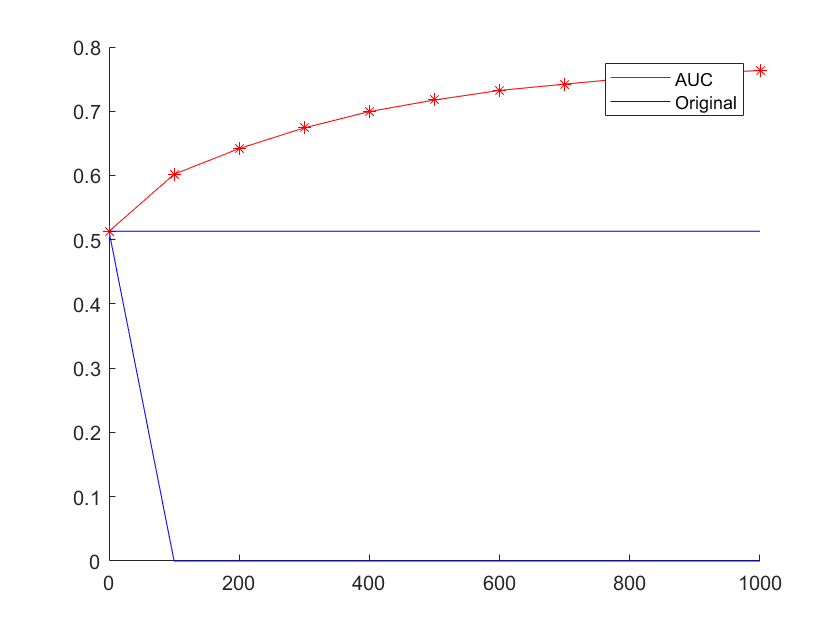

hold on
plot(0:100:1000,auc,'-r');
plot(0:100:1000,original_auc,'-b');
hold off
legend('AUC','Original');